# State Estimation of Formation Control Systems

This the final project for course *ET4386 Estimation and Detection*.

clear all;
clc;
close all;

## 1. Data Load

- dt: The time interval

- K: Max iterations

- N: Number of Agents (7)

- M: Number of Edges (12)

- z: Actual positions of each agent (2D position)

- z*: Target positions of each agent

- L: Edge weights ($l_{ij} $: the weight of the edge between positions of the i-th and j-th agent)

- R: The covariance matrix of the noise

load("data.mat");

## 2. Initialization

disp(L); % take a look to the weight

    0.2741   -0.2741   -0.2741    0.1370    0.1370         0         0
   -0.2741    0.6852         0   -0.5482         0         0    0.1370
   -0.2741         0    0.6852         0   -0.5482    0.1370         0
    0.1370   -0.5482         0    0.7537   -0.0685   -0.2741         0
    0.1370         0   -0.5482   -0.0685    0.7537         0   -0.2741
         0         0    0.1370   -0.2741         0    0.2741   -0.1370
         0    0.1370         0         0   -0.2741   -0.1370    0.2741



z_matrix = zeros(7, 2, K); % the matrix containing the positions of all agents for K iterations
z_matrix(:, :, 1) = z;     % initialize the position of the 1-st iteration
k = 1; % current iteration
% u_matrix = zeros(7, 2, K) % control variable matrix

## 3. Control without Noise

The project aims to implement a relative formation control system affected by measurement noise. We will discuss the impact of different estimators and various T noisy measurements on the system.

First, we implement a noise-free relative formation control based on the pseudocode provided in the assignment.

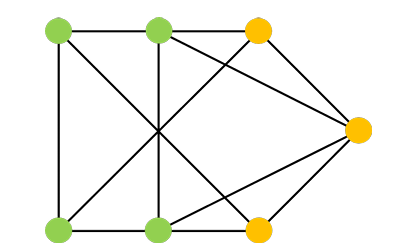

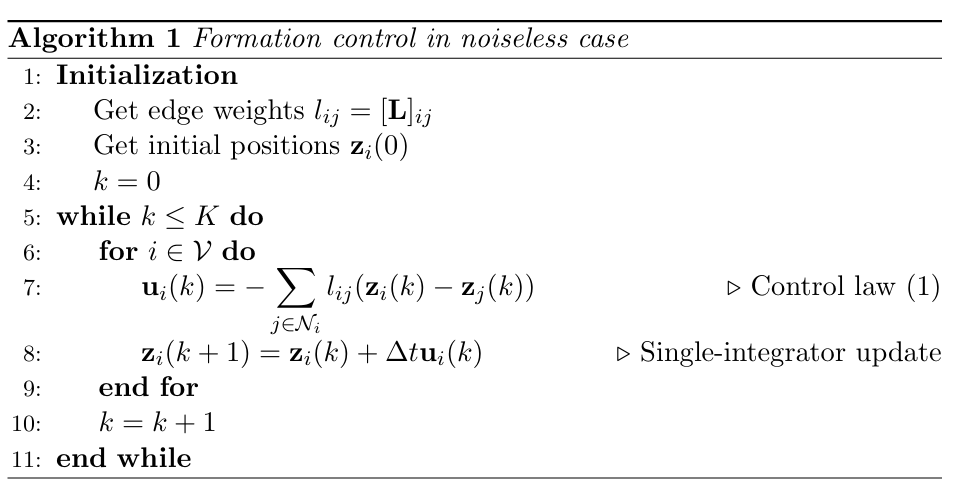

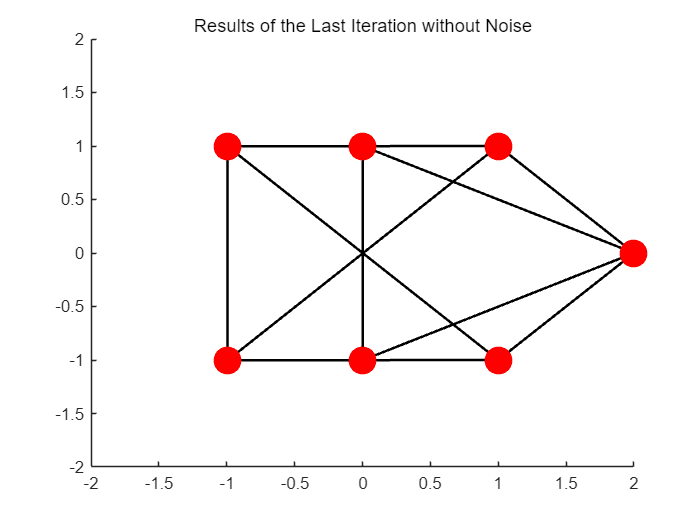

% the hyperparameters used by the reference
% dt = 0.001;
% K = 30000;

dt = 0.05;
K = 5000;

while k <= K
    for i = 1:N
        % iterate to get the new position for agent i at time k
        u_i_k = zeros(1, 2); % initialize the control variable
        z_i_k = z_matrix(i, :, k); % get the old position

        % traverse weight L(i, j) to compute the control variable ui(k)
        for j = 1:N
            u_i_k = u_i_k + L(i, j) * (z_matrix(i, :, k) - z_matrix(j, :, k));
        end

        % for the first three agents, assuming they stay in the target locations from the beginning
        if i == 1|| i==2 || i==3
            u_i_k = 0;
        end

        z_i_k_new = z_i_k + dt * u_i_k; % calculate new position using zi(k+1) = zi(k) + dt*ui(k)
        z_matrix(i, :, k+1) = z_i_k_new; % record the new position with z_matrix
    end

    k = k + 1;
end

% calculate the errors
error = compute_error(z_matrix, z_star, K);

% plot the result
plot_formation(z_matrix(:, :, K));
title("Results of the Last Iteration without Noise")

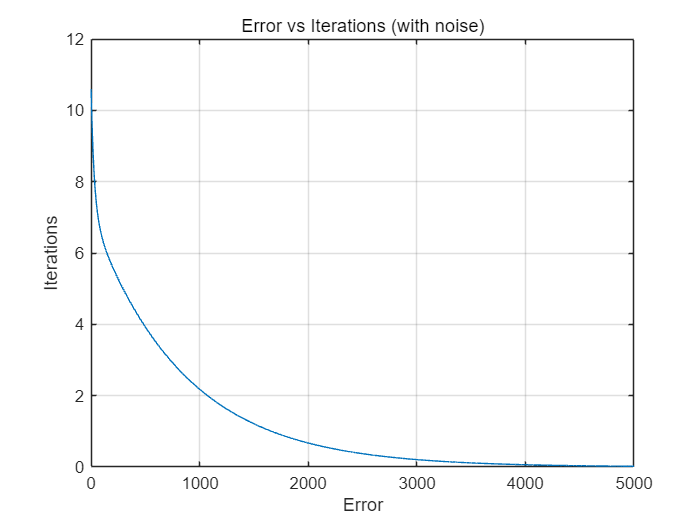

% plot the errors comparing to iterations
figure;
plot(error); 
xlabel("Error");
ylabel("Iterations");
title("Error vs Iterations (with noise)");
grid on;

## 4. Add Noise and Observation

Next, we simulate the scenario with noise. The noise is added according to covariance matrix R.

The result shows that the noise introduces instability. Overall, there is a convergence trend, but it ultimately fails to converge to the ideal position.

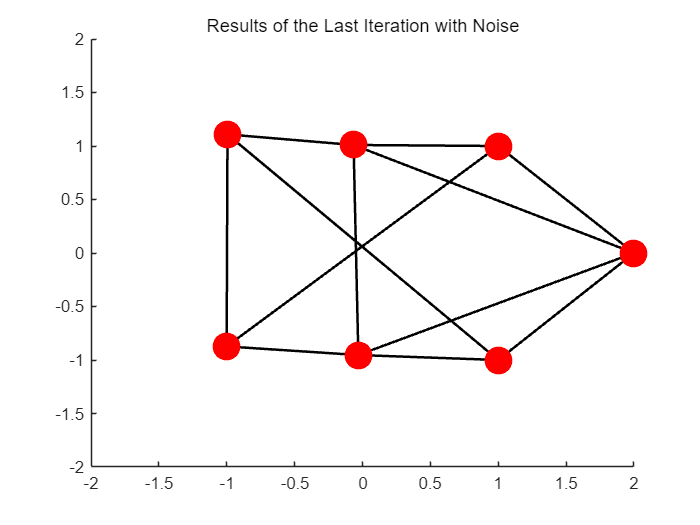

% initialize
z_matrix2 = zeros(7, 2, K);
z_matrix2(:, :, 1) = z;
k = 1;

% retain the observations, i.e. the measurements
% since there are only 12 non-zero edges, only 12 vectors are needed
observations_m = zeros(12, 2, K);

% start iteration
while k <= K
    state_num = 0;

    for i = 1:N
        % iterate to get the new position for agent i at time k
        u_i_k = zeros(1, 2); % initialize the control variable
        z_i_k = z_matrix2(i, :, k);
        
        % traverse weight L(i, j) to compute the control variable ui(k)
        for j = 1:N
            y_k = z_matrix2(i, :, k) - z_matrix2(j, :, k) + mvnrnd([0, 0], R);
            u_i_k = u_i_k + L(i, j) * y_k;

            % x_matrix(i, j, :, k) = x; % problematic, only need to retain where L is non-zero.
            % retain the measurement
            % 1. Only retain measurements where L is non-zero 
            %    and not self-loops
            % 2. Only keep non-zero values in the lower triangular 
            %    matrix of L (since L is a symmetric matrix).
            if (L(i, j) ~= 0 && i < j)
                state_num = state_num + 1;
                observations_m(state_num, :, k) = y_k;
            end
        end
        
        % for the first three agents, assuming they stay in the target locations from the beginning
        if i == 1|| i==2 || i==3
            u_i_k = 0;
        end

        z_i_k_new = z_i_k + dt * u_i_k; % calculate new position using zi(k+1) = zi(k) + dt*ui(k)
        z_matrix2(i, :, k+1) = z_i_k_new; % record the new position with z_matrix
    end

    k = k + 1;
end

% calculate the errors
error = compute_error(z_matrix2, z_star, K);

% plot the trajectories
plot_formation(z_matrix2(:, :, K));
title("Results of the Last Iteration with Noise")

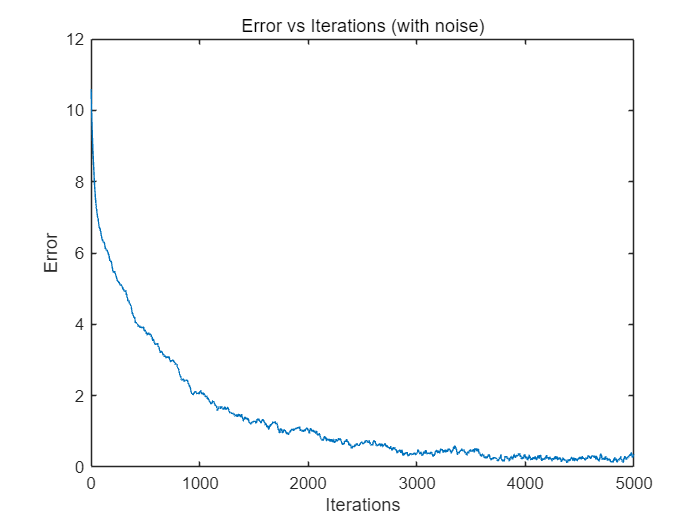

% plot errors compating to iterations
figure;
plot(error);
xlabel("Iterations");
ylabel("Error");
title("Error vs Iterations (with noise)");

## 5. Applying Different Estimators

In the following section, we will apply different estimators with different number of measurements T, and observe their effects.

% 这里设置估计器的共同参数，用于对比
max_iter = 2000;    % 最大迭代次数
T = 20;             % 每对节点的观测次数 10 100
dt = 0.1;           % 步长

## 5.1 实现无偏估计器


z_matrix_2 = zeros(7, 2, max_iter + 1); % 状态矩阵 (7个节点，2维，k次迭代)
z_matrix_2(:, :, 1) = z; % 初始状态
state_matrix = zeros(24, 2, max_iter); % 保存每次迭代的平均状态
noise_matrix = zeros(24, 2, max_iter); % 保存每次迭代的平均噪声
k = 1; % 当前迭代次数

vec_T = ones(T, 1);
dimension = 2;
I_Dimension = eye(2);


for k = 1:max_iter
    for i = 1:N
        % 初始化输入
        u_i_k = zeros(1, dimension);
        
        % 遍历邻居节点
        for j = 1:N
            if L(i, j) ~= 0 && i ~= j
                % 构造测量值
                vij_m = mvnrnd(zeros(1, T * dimension), kron(R, eye(T)));
                H = kron(vec_T, I_Dimension);
                dz = z_matrix_2(i, :, k) - z_matrix_2(j, :, k);
                x_state_m = H * dz' + vij_m';
                
                % 计算平均观测值
                x_avg = (1 / T) * kron(vec_T', I_Dimension) * x_state_m;
                
                % 累加输入
                u_i_k = u_i_k + L(i, j) * x_avg';
            end
        end
        
        % 更新状态（固定节点不更新）
        if i == 1 || i == 2 || i == 3
            u_i_k = 0;
        end
        z_i_k_new = z_matrix_2(i, :, k) + dt * u_i_k;
        z_matrix_2(i, :, k + 1) = z_i_k_new;
    end
end



## 可视化最终结果（无偏估计器）

figure;
plot_formation(z_matrix_2(:, :, max_iter));
title("Results Using Unbiased Estimator");
error_Unbiased = compute_error(z_matrix_2, z_star, max_iter);
figure;
plot(error_Unbiased);

xlabel("Iterations");
ylabel("Error");
title("Error versus Iterations Using Unbiased Estimator");

## 5.2 MLE估计器

% 初始化参数

z_matrix_2 = zeros(7, 2, max_iter + 1); % 状态矩阵
z_matrix_2(:, :, 1) = z;                % 初始状态
T = 10;                                 % 每对节点的观测次数
vec_T = ones(T, 1);                     % T x 1 全1向量
dimension = 2;                          % 状态维度
I_Dimension = eye(dimension);           % D x D 单位矩阵

% 开始迭代
for k = 1:max_iter
    for i = 1:N
        % 初始化输入
        u_i_k = zeros(1, dimension);
        
        % 遍历邻居节点
        for j = 1:N
            if L(i, j) ~= 0 && i ~= j
                % 构造测量值
                vij_m = mvnrnd(zeros(1, T * dimension), kron(R, eye(T)));
                H = kron(vec_T, I_Dimension);
                dz_true = z_matrix_2(i, :, k) - z_matrix_2(j, :, k);
                x_state_m = H * dz_true' + vij_m'; % 带噪声的观测值
                
                % 计算 MLE 解
                Sigma_v = kron(R, eye(T)); % 协方差矩阵
                Sigma_v_inv = inv(Sigma_v); % 逆矩阵
                dz_mle = inv(H' * Sigma_v_inv * H) * H' * Sigma_v_inv * x_state_m; % MLE 解
                
                % 累加输入
                u_i_k = u_i_k + L(i, j) * dz_mle';
            end
        end
        
        % 更新状态（固定节点不更新）
        if i == 1 || i == 2 || i == 3
            u_i_k = 0;
        end
        z_i_k_new = z_matrix_2(i, :, k) + dt * u_i_k;
        z_matrix_2(i, :, k + 1) = z_i_k_new;
    end
end


## 可视化最终结果（MLE）

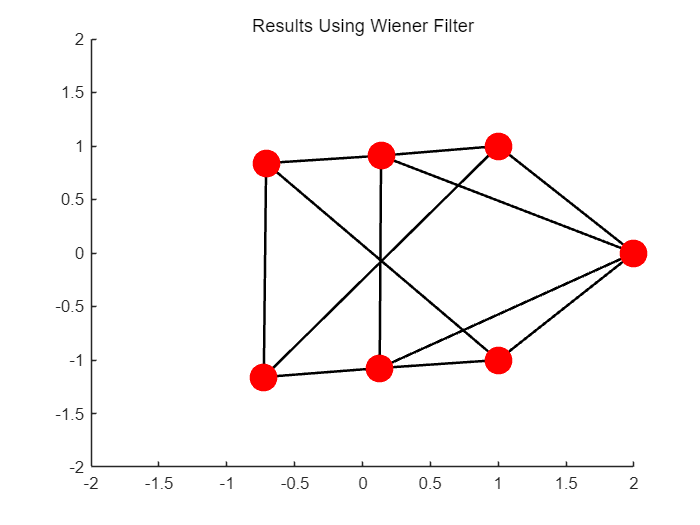


figure;
plot_formation(z_matrix_2(:, :, max_iter)); % 绘制最终状态
title("Results Using MLE Estimator");
figure;
error_MLE = compute_error(z_matrix_2, z_star, max_iter);
title("Results Using MLE Estimator");
plot(error_MLE);
xlabel("Iterations");
ylabel("Error");
title("Error versus Iterations Using MLE Estimator");

%% 5.3 Wiener估计器
% 初始化参数
z_matrix_2 = zeros(7, 2, max_iter + 1); % 状态矩阵 (7个节点，2维，k次迭代)
z_matrix_2(:, :, 1) = z;                % 初始状态
dimension = 2;                          % 状态维度
vec_T = ones(T, 1);                     % T x 1 全1向量
I_Dimension = eye(dimension);           % D x D 单位矩阵
R = [0.1, 0; 0, 0.2];                   % 测量噪声协方差
Q = 0.01 * eye(dimension);              % 状态噪声协方差

% 构造测量矩阵
H = kron(vec_T, I_Dimension);           % TD x D 测量矩阵
Sigma_v = kron(R, eye(T));              % TD x TD 测量噪声协方差矩阵

% 计算维纳滤波器权重矩阵 W
W = Q * H' / (H * Q * H' + Sigma_v);    % D x TD 滤波器权重矩阵

% 迭代过程
for k = 1:max_iter
    for i = 1:N
        % 初始化输入
        u_i_k = zeros(1, dimension);
        
        % 遍历邻居节点
        for j = 1:N
            if L(i, j) ~= 0 && i ~= j
                % 生成带噪声的观测值
                dz_true = z_matrix_2(i, :, k) - z_matrix_2(j, :, k); % 相对状态
                vij_m = mvnrnd(zeros(1, T * dimension), Sigma_v); % 噪声
                x_state_m = H * dz_true' + vij_m'; % 带噪声测量值
                
                % 使用维纳滤波器估计 dz
                dz_estimate = W * x_state_m; % 维纳滤波器的估计结果
                
                % 累加输入
                u_i_k = u_i_k + L(i, j) * dz_estimate';
            end
        end
        
        % 更新状态（固定节点不更新）
        if i == 1 || i == 2 || i == 3
            u_i_k = 0;
        end
        z_i_k_new = z_matrix_2(i, :, k) + dt * u_i_k;
        z_matrix_2(i, :, k + 1) = z_i_k_new; % 保存更新后的状态
    end
end

% 可视化最终结果
figure;
plot_formation(z_matrix_2(:, :, max_iter)); % 自定义绘图函数
title("Results Using Wiener Filter");

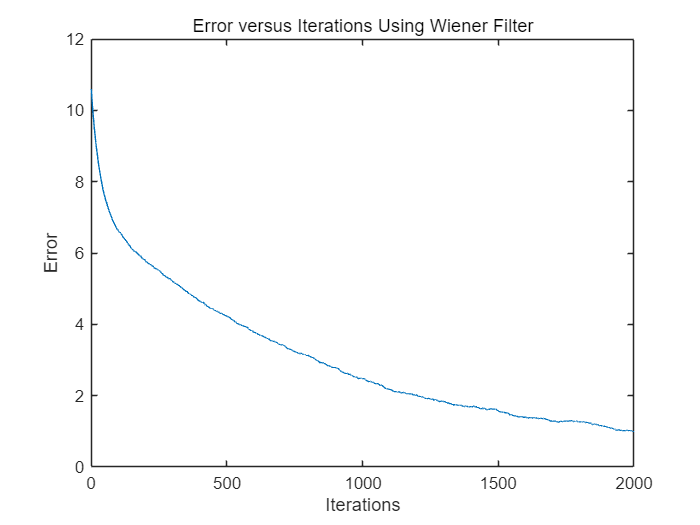

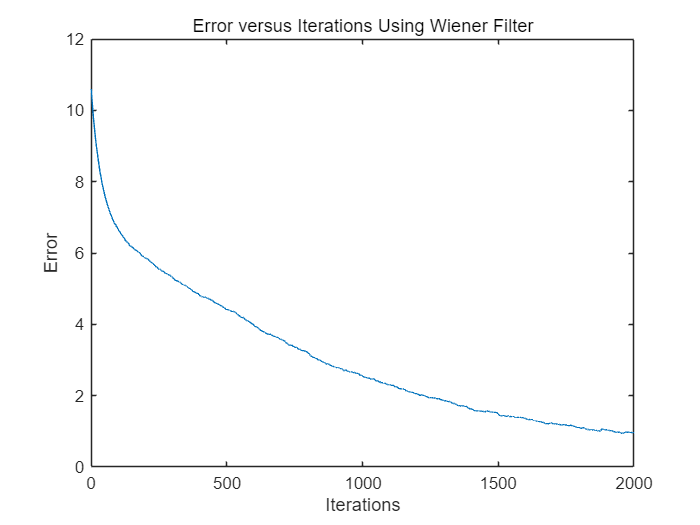

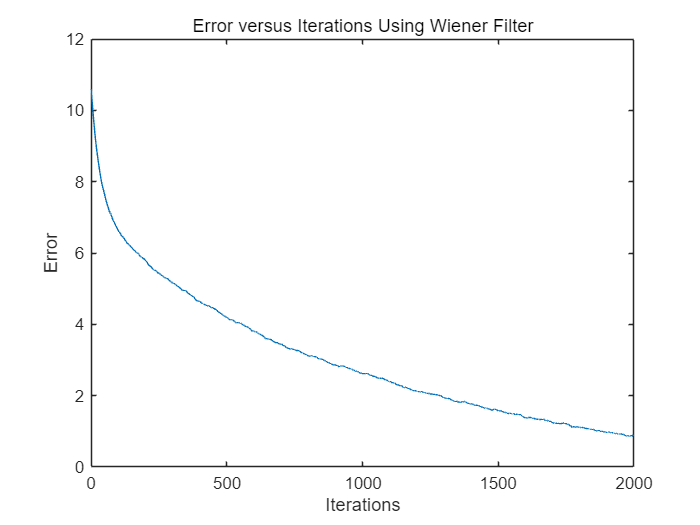

error_Wiener = compute_error(z_matrix_2, z_star, max_iter);
figure;
plot(error_Wiener);
xlabel("Iterations");
ylabel("Error");
title("Error versus Iterations Using Wiener Filter");